# パラメータ化拡張GFT

2024年4月29日

村松正吾，内藤翼（新潟大学）

#### 参考文献:

- H. Kitamura, H. Yasuda, Y. Tanaka and S. Muramatsu, "Realization of DiGraph Filters Via Augmented GFT," 2023 IEEE International Conference on Image Processing (ICIP), Kuala Lumpur, Malaysia, 2023, pp. 2885-2889, doi: 10.1109/ICIP49359.2023.10222618.

- Abstract: This study proposes a filtering method for directed graph (digraph) signals. In order to realize digraph filtering, a novel graph Fourier transform (GFT), – Augmented GFT (AuGFT) –, is proposed by defining an Hermitian adjacency matrix. Although there has been the same method to give the adjacency matrix of digraphs, this study defines a novel digraph Laplacian. The existing digraph Laplacian does not give the graph signal variation considering the edge directions, while the novel one does. This paper introduces three important ideas. The first is the definition of a novel degree matrix to give the novel digraph Laplacian. The second is to decompose the symmetric and skew-symmetric components of the novel digraph Laplacian independently into their spectral components. The third is, based on the decomposition, to augment the conventional GFT for digraphs as an invertible real-valued dictionary. The new GFT is shown to provide a practical form of real-valued digraph filtering. The significance of the proposed method is verified through simulations of signal filtering on digraphs.

- URL: [https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=10222618&isnumber=10221892](https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=10222618&isnumber=10221892)

**謝辞：**

- 本研究は[科研費21H04596](https://kaken.nii.ac.jp/ja/grant/KAKENHI-PROJECT-21H04596/)および[科研費22H00512](https://kaken.nii.ac.jp/ja/grant/KAKENHI-PROJECT-22H09512/)助成による。

## 各種設定

isDiGraph = true; % 有向グラフとして解析

if ~exist('./gspbox','dir')
    setup
else
    addpath('gspbox')
end
gsp_start

GSPBox version 0.7.5. Copyright 2013-2015 LTS2-EPFL,
by Nathanael Perraudin, Johan Paratte, David Shuman and Vassilis Kalofolias


RESULTS_DIR = "../results/";
FIGEXT = ".png";

## 有向グラフの隣接行列 $\mathbf{A}$ の生成

有向グラフ $\mathcal{G}$ の定義

s = [1 1 2 2 3 3 4 4 4 5];
t = [2 3 4 5 6 7 8 9 10 4];
G = digraph(s,t)

G =   digraph のプロパティ:

    Edges: [10×1 table]
    Nodes: [10×0 table]


有向非巡回性の確認

isdag(G)

ans = logical
   1


有向グラフ $\mathcal{G}$ のエッジ $\mathcal{E}$

G.Edges

ans = 10×1 table
    EndNodes
    ________

    1     2 
    1     3 
    2     4 
    2     5 
    3     6 
    3     7 
    4     8 
    4     9 
    4    10 
    5     4 


有向グラフ $\mathcal{G}$ のノード $\mathcal{V}$ 

G.Nodes


ans =

  10×0 の空の table



## 有向グラフ $\mathcal{G}$の描画

A = full(adjacency(G,'weighted'))

A =      0     1     1     0     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     1     1     1
     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


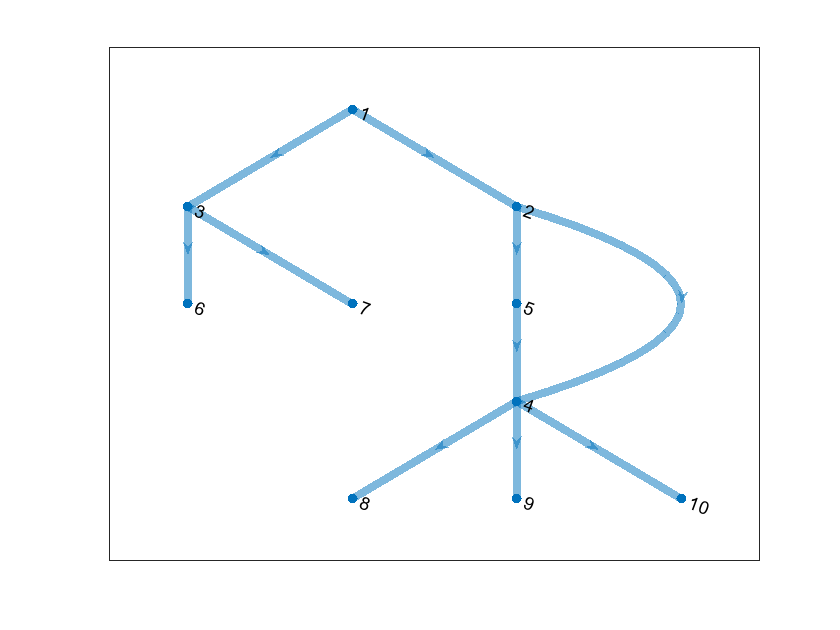

figure
h = plot(G,'LineWidth',4,'Layout','layered');

if ~isDiGraph
    if isa(A,'digraph') || isa(A,'graph')
        A = adjacency(A);
    end
    A = (A+A.')/2;
end
[U,Q,C,D,L,Lmd,Sgm] = fcn_digraphops(A)

U =     0.2531    0.0136   -0.0000   -0.0000   -0.0000   -0.5340    0.6691    0.0443   -0.4458    0.0475
    0.1507   -0.1399   -0.0000    0.0000   -0.0000   -0.4741   -0.0484   -0.6651    0.4861   -0.2281
    0.3839    0.1673   -0.0000    0.0000   -0.0000   -0.0710    0.2010    0.5793    0.6659   -0.0141
    0.1405   -0.2829         0    0.0000   -0.0000   -0.0788   -0.0996   -0.0864    0.1066    0.9302
    0.1379   -0.2101   -0.0000    0.0000   -0.0000   -0.5416   -0.6489    0.3884   -0.2294   -0.1378
    0.5502    0.2798   -0.5293    0.2619   -0.3889    0.1805   -0.1695   -0.1730   -0.1665    0.0022
    0.5502    0.2798    0.5293   -0.2619    0.3889    0.1805   -0.1695   -0.1730   -0.1665    0.0022
    0.2014   -0.4731   -0.4863   -0.6044    0.2548    0.2003    0.0840    0.0258   -0.0267   -0.1429
    0.2014   -0.4731    0.4493   -0.0946   -0.6752    0.2003    0.0840    0.0258   -0.0267   -0.1429
    0.2014   -0.4731    0.0370    0.6990    0.4204    0.2003    0.0840    0.0258   -0.0

Q =     0.3505    0.0234    0.5908    0.0508   -0.4146   -0.0124
    0.0426   -0.6365    0.0127   -0.1472   -0.0226    0.7555
    0.0145   -0.2172    0.0777   -0.9035    0.0108   -0.3608
   -0.8248    0.2759    0.3280   -0.1490   -0.2398    0.2372
   -0.3747   -0.3562    0.0010    0.1773    0.5444   -0.2281
   -0.0892   -0.0060   -0.5080   -0.0437   -0.3790   -0.0113
   -0.0892   -0.0060   -0.5080   -0.0437   -0.3790   -0.0113
    0.1133    0.3387   -0.0838   -0.1844    0.2492    0.2519
    0.1133    0.3387   -0.0838   -0.1844    0.2492    0.2519
    0.1133    0.3387   -0.0838   -0.1844    0.2492    0.2519


C =    0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.5000 + 0.5000i
   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   

D =     1.4142         0         0         0         0         0         0         0         0         0
         0    2.1213         0         0         0         0         0         0         0         0
         0         0    2.1213         0         0         0         0         0         0         0
         0         0         0    3.5355         0         0         0         0         0         0
         0         0         0         0    1.4142         0         0         0         0         0
         0         0         0         0         0    0.7071         0         0         0         0
         0         0         0         0         0         0    0.7071         0         0         0
         0         0         0         0         0         0         0    0.7071         0         0
         0         0         0         0         0         0         0         0    0.7071         0
         0         0         0         0         0         0         0         0       

L =    1.4142 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.5000 + 0.5000i   2.1213 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.5000 + 0.5000i   0.0000 + 0.0000i   2.1213 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i   3.5355 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i
   0.0000 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i  -0.5000 - 0.5000i   1.4142 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -

Lmd =     0.3583         0         0         0         0         0         0         0         0         0
         0    0.4081         0         0         0         0         0         0         0         0
         0         0    0.7071         0         0         0         0         0         0         0
         0         0         0    0.7071         0         0         0         0         0         0
         0         0         0         0    0.7071         0         0         0         0         0
         0         0         0         0         0    0.9038         0         0         0         0
         0         0         0         0         0         0    1.3002         0         0         0
         0         0         0         0         0         0         0    2.3817         0         0
         0         0         0         0         0         0         0         0    2.7062         0
         0         0         0         0         0         0         0         0     

Sgm =          0    1.2177         0         0         0         0
   -1.2177         0         0         0         0         0
         0         0         0    0.8892         0         0
         0         0   -0.8892         0         0         0
         0         0         0         0         0    0.4760
         0         0         0         0   -0.4760         0


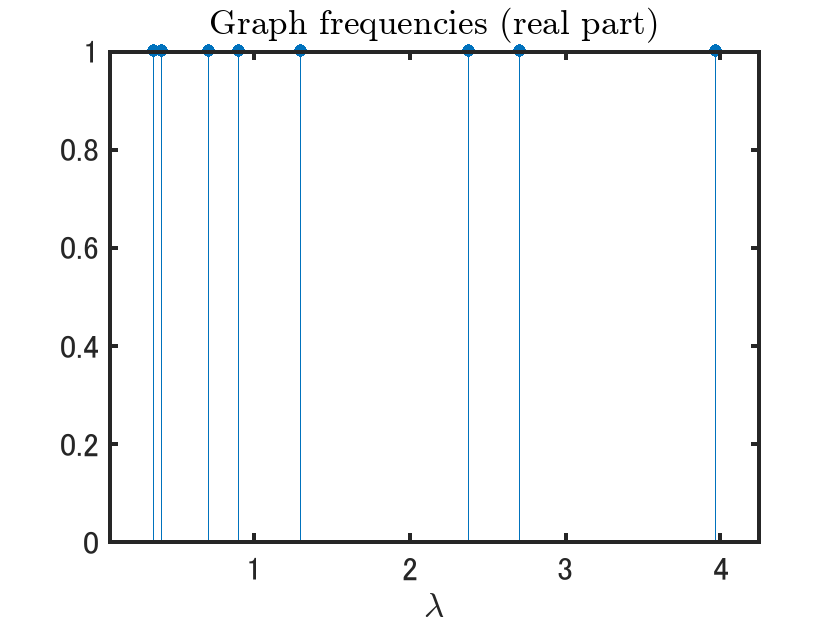

y = ones(1,size(Lmd,2));
stem(diag(Lmd),y,'filled')
title('Graph frequencies (real part)','Interpreter','latex')
xlabel('$\lambda$','Interpreter','latex')

ax = gca;
ax.LineWidth = 2;
ax.FontSize = 16;
exportgraphics(ax,RESULTS_DIR+"EigenValues_sym"+FIGEXT)

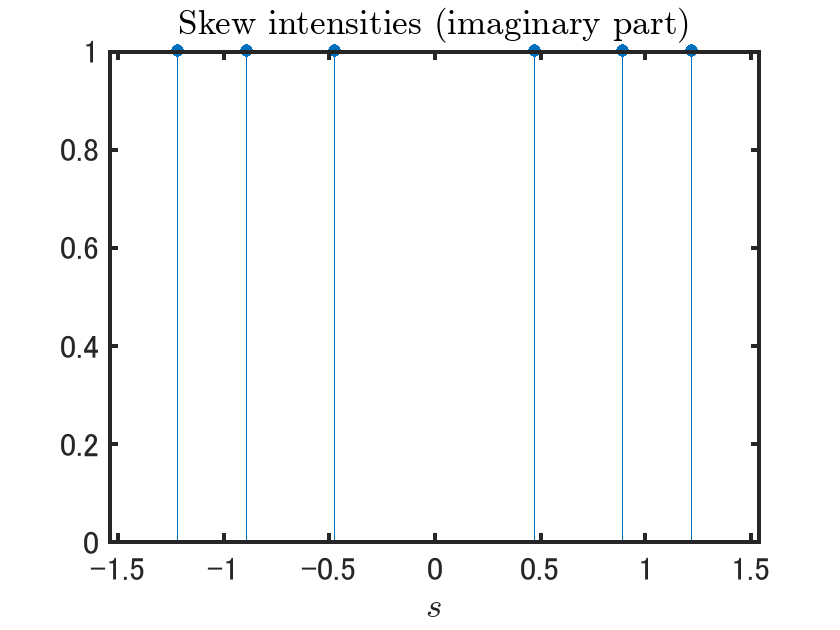

sgm = sort([diag(Sgm,1);diag(Sgm,-1)],'ascend');
idxg = find(sgm);
gma = sgm(idxg);
if ~isempty(gma)
    y = ones(1,length(gma));
    stem(gma,y,'filled')
    title('Skew intensities (imaginary part)','Interpreter','latex')
    xlabel('$s$','Interpreter','latex')

    ax = gca;
    ax.LineWidth = 2;
    ax.FontSize = 16;
    %exportgraphics(ax,RESULTS_DIR+"EigenValues_skw"+FIGEXT)
end

## $\;{\mathbf{u}}_{\lambda_k }$拡張GFT（対称成分）の基底ベクトル

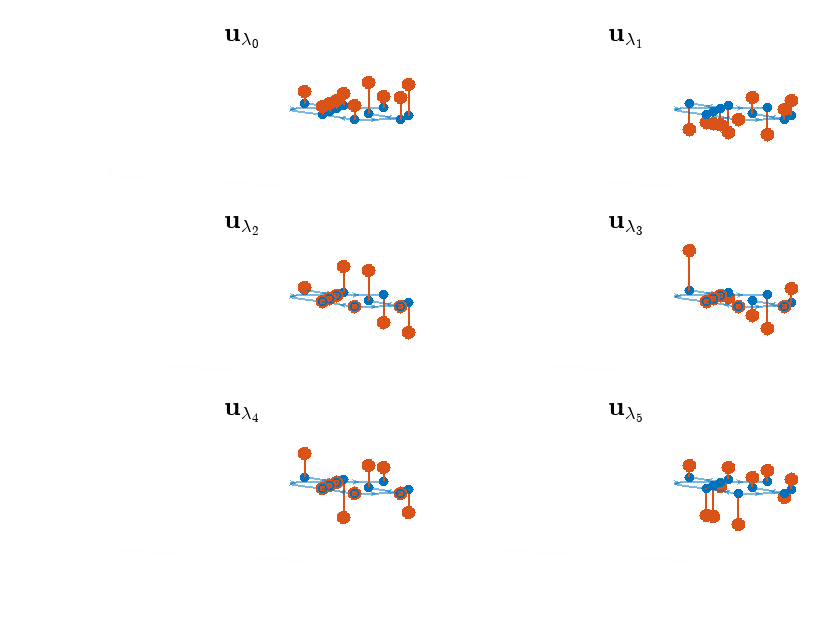

zscale = .8;
fontSize = 12; %36;
lineWidth = 1; %3;
arrowSize = 4; %12;
az = 200;
el = 20;
figure
tiledlayout(3,2)
for k = 0:5
    %figure
    nexttile
    %uk = U(:,k+1)*Lmd(k+1,k+1);
    uk = U(:,k+1);
    %
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;
    p1.NodeLabel = {};
    hold on
    stem3(p1.XData,p1.YData,uk,'fill','LineWidth',lineWidth);
    %zlim(zscale*[-1 1])
    %axis off
    title("$\mathbf{u}_{\lambda_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    %exportgraphics(ax,RESULTS_DIR+"u"+num2str(k)+FIGEXT)
end

## $\;{\mathit{\mathbf{q}}}_{s_k }$拡張GFT（交代成分）の基底ベクトル

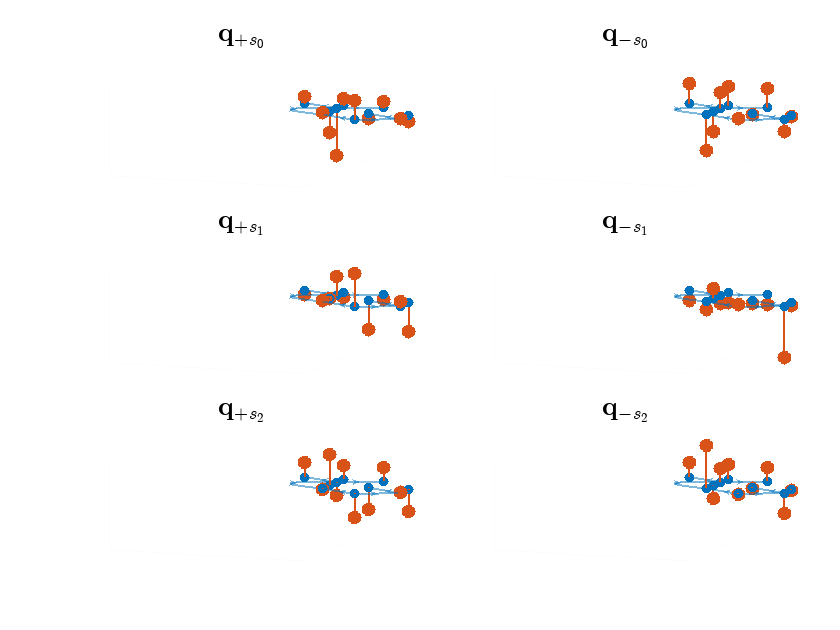

figure
tiledlayout(3,2)
for k = 0:min(5,length(gma)/2-1)
    %figure
    nexttile
    qkp = Q(:,2*k+1);
    % +sk
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;
    p1.NodeLabel = {};
    hold on
    stem3(p1.XData,p1.YData,qkp,'fill','LineWidth',lineWidth);
    title("$\mathbf{q}_{+s_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    %exportgraphics(ax,RESULTS_DIR+"qp"+num2str(k)+FIGEXT)
    %
    %figure
    nexttile
    qkm = Q(:,2*k+2);
    % -sk
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;
    p1.NodeLabel = {};
    hold on
    stem3(p1.XData,p1.YData,qkm,'fill','LineWidth',lineWidth);
    title("$\mathbf{q}_{-s_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    %exportgraphics(ax,RESULTS_DIR+"qm"+num2str(k)+FIGEXT)
end

## 
$$\;$$


## 変動の確認


$$\mathbf{L}=\left(\begin{array}{cccc}
d_{11} & -b_{12} & -b_{13} & -b_{14}\\
-\bar{b}_{12} & d_{22} & -b_{23} & -b_{24}\\
-\bar{b}_{13} & -\bar{b}_{23} & d_{33} & -b_{34}\\
-\bar{b}_{14} & -\bar{b}_{24} & -\bar{b}_{34} & d_{44}
\end{array}\right)$$



$$\underbrace{\left(\begin{array}{c}
y_{1}\\
y_{2}\\
y_{3}\\
y_{4}
\end{array}\right)}_{\mathbf{y}}=\underbrace{\left(\begin{array}{cccc}
d_{11} & -b_{12} & -b_{13} & -b_{14}\\
-\bar{b}_{12} & d_{22} & -b_{23} & -b_{24}\\
-\bar{b}_{13} & -\bar{b}_{23} & d_{33} & -b_{34}\\
-\bar{b}_{14} & -\bar{b}_{24} & -\bar{b}_{34} & d_{44}
\end{array}\right)}_{\mathbf{L}}\underbrace{\left(\begin{array}{c}
x_{1}\\
x_{2}\\
x_{3}\\
x_{4}
\end{array}\right)}_{\mathbf{x}}$$



$$d_{k,k}:=\sum_{\ell\in\mathcal{N}\backslash \{k\}} |c_{k,\ell}|=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  |c_{\ell,k}|=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  \sqrt{c_{k,\ell}b_{\ell,k}}=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  \sqrt{c_{k,\ell}\bar{c}_{k,\ell}}

$$


ただし， $\mathcal{N}:=\{1,2,\cdots,N\}$。


$$y_{k}=d_{k,k}x_k-\sum_{\ell=k+1}^{N} b_{k,\ell}x_\ell-\sum_{\ell=1}^{k-1} \bar{b}_{k,\ell}x_\ell$$



$$\Delta_{\mathbf{L}}(\mathbf{x})=\mathbf{x}^T\mathbf{L}\mathbf{x}=\sum_{k\in\mathcal{N}}\sum_{\ell=k+1}^N |b_{k,\ell}|\cdot|x_k-e^{-j\angle b_{k,\ell}} x_\ell|^2$$


行列計算

nDims = size(L,1);
x = randn(nDims,1);
xLx = x.'*L*x

xLx = 16.6684 + 0.0000i

累積加算

tv = 0;
for iRow = 1:nDims
    xk = x(iRow);
    for iCol = iRow+1:nDims
        ckl = C(iRow,iCol);
        xl = x(iCol);
        tv = tv + abs(ckl)*abs(xk-exp(1j*angle(ckl))*xl)^2;
    end
end
tv

tv = 16.6684

誤差評価

assert(abs(xLx - tv)<1e-6,'Invalid TV')

waterlevel = randn(nDims)

waterlevel =    -1.2507    0.9337   -0.0308   -1.6642    1.0826    0.5946   -1.9488   -0.9485   -0.1319   -0.4711
   -0.9480    0.3503    0.2323   -0.5900    1.0061    0.3502    1.0205    0.4115   -0.1472    0.1370
   -0.7411   -0.0290    0.4264   -0.2781   -0.6509    1.2503    0.8617    0.6770    1.0078   -0.2919
   -0.5078    0.1825   -0.3728    0.4227    0.2571    0.9298    0.0012    0.8577   -2.1237    0.3018
   -0.3206   -1.5651   -0.2365   -1.6702   -0.9444    0.2398   -0.0708   -0.6912   -0.5046    0.3999
    0.0125   -0.0845    2.0237    0.4716   -1.3218   -0.6904   -2.4863    0.4494   -1.2706   -0.9300
   -3.0292    1.6039   -2.2584   -1.2128    0.9248   -0.6516    0.5812    0.1006   -0.3826   -0.1768
   -0.4570    0.0983    2.2294    0.0662    0.0000    1.1921   -2.1924    0.8261    0.6487   -2.1321
    1.2424    0.0414    0.3376    0.6524   -0.0549   -1.6118   -2.3193    0.5362    0.8257    1.1454
   -1.0667   -0.7342    1.0001    0.3271    0.9111   -0.0245    0.0799    0.89

## AuGFTによるフィルタ処理

パラメータ $\alpha$ を導入し一般化したAuGFT

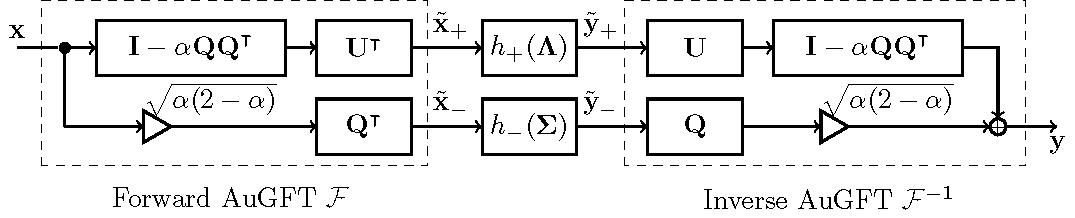

- 
$$0\leq \alpha \leq 1$$


- 
$$\beta = \sqrt{\alpha(2-\alpha)$$


syms alpha beta
eqn1 = alpha == (1-sqrt(1-beta^2));
eqn2 = beta <= 1;
eqn3 = beta >= 0;
eqn4 = alpha <= 1;
eqn5 = alpha >= 0;
eqns = [eqn1; eqn2; eqn3; eqn4; eqn5]

$$eqns = \left(\begin{array}{c} \alpha =1-\sqrt{1-\beta^{2}}\\ \beta \leq 1\\ 0\leq \beta \\ \alpha \leq 1\\ 0\leq \alpha \end{array}\right)$$

res = solve(eqns,beta,'ReturnConditions',true)

res = フィールドをもつ struct :
          beta: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]


res.beta

$$ans = \left(\begin{array}{c} 0\\ \sqrt{-\alpha \,\left(\alpha -2\right)} \end{array}\right)$$

res.conditions

$$ans = \left(\begin{array}{c} \alpha =0\\ 0<\alpha \wedge \alpha <1 \end{array}\right)$$

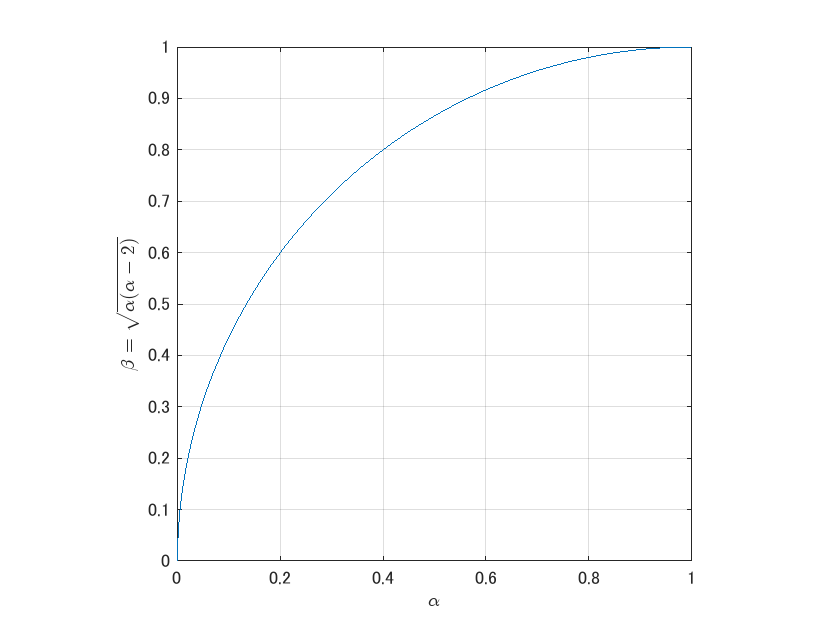

figure
fplot(@(x) sqrt(x.*(2-x)),[0 1])
xlabel('$\alpha$','Interpreter','latex')
ylabel('$\beta=\sqrt{\alpha(\alpha-2)}$','Interpreter','latex')
axis equal
grid on

rmse = @(rx,ry) norm(rx(:)-ry(:),2)/sqrt(numel(rx));

x = waterlevel;
freqXSet = fcn_fwdAuGFT(x,U,Q)

freqXSet =    -2.1963    0.5604    0.5865   -1.0931    0.0519    0.0153   -1.9107    0.5392   -0.7584   -0.8780
   -0.2317    0.6693   -1.1353   -0.1882   -0.4513   -0.2201    1.2774   -0.6612    0.2042    0.1960
   -0.8690    0.8373   -3.1619   -0.6186    1.1981   -1.2842    1.6507   -0.3122    0.4880    1.9267
    0.2098   -1.0188    0.4412    0.5681    0.0536   -0.5953    0.7969    0.1690   -1.4122    0.5433
   -2.5866    0.3451   -0.9048   -0.9412    1.2938    1.3968    2.2339    0.0903   -0.4736   -1.2881
    0.7813    0.2354    0.4412    1.7507   -0.3116   -0.7836   -0.1738    0.8373    0.3083   -0.3100
   -0.1155    0.9140    0.4074    0.1036    0.8974    0.4058   -0.8068   -0.0374    0.7012   -0.4293
    0.3162   -0.7870    0.1398   -0.3624   -0.9101    0.5316   -0.1866   -0.2322    0.6410   -0.0358
    0.3786   -0.0815    0.1888    0.8625   -0.1190    0.7178    2.0897    0.8834    0.6909    0.2813
   -0.0850    0.3117   -0.6449    0.4561    0.0492    0.5817    0.3200    0.3136

y = fcn_invAuGFT(freqXSet,U,Q)

y =    -1.2507    0.9337   -0.0308   -1.6642    1.0826    0.5946   -1.9488   -0.9485   -0.1319   -0.4711
   -0.9480    0.3503    0.2323   -0.5900    1.0061    0.3502    1.0205    0.4115   -0.1472    0.1370
   -0.7411   -0.0290    0.4264   -0.2781   -0.6509    1.2503    0.8617    0.6770    1.0078   -0.2919
   -0.5078    0.1825   -0.3728    0.4227    0.2571    0.9298    0.0012    0.8577   -2.1237    0.3018
   -0.3206   -1.5651   -0.2365   -1.6702   -0.9444    0.2398   -0.0708   -0.6912   -0.5046    0.3999
    0.0125   -0.0845    2.0237    0.4716   -1.3218   -0.6904   -2.4863    0.4494   -1.2706   -0.9300
   -3.0292    1.6039   -2.2584   -1.2128    0.9248   -0.6516    0.5812    0.1006   -0.3826   -0.1768
   -0.4570    0.0983    2.2294    0.0662    0.0000    1.1921   -2.1924    0.8261    0.6487   -2.1321
    1.2424    0.0414    0.3376    0.6524   -0.0549   -1.6118   -2.3193    0.5362    0.8257    1.1454
   -1.0667   -0.7342    1.0001    0.3271    0.9111   -0.0245    0.0799    0.8979   -1.0


rmse(waterlevel,y)

ans = 5.9556e-16

assert(norm(x(:)-y(:))<1e-6)

任意のα

alpha = rand()

alpha = 0.1062

freqXSet = fcn_fwdAuGFT(x,U,Q,alpha)

freqXSet =    -2.4383    0.7157    0.6557   -1.0243    0.0416    0.0178   -1.9415    0.7467   -0.8192   -0.9860
   -0.4081    0.8434   -1.4058   -0.3598   -0.5622   -0.2777    1.4530   -0.8580    0.2106    0.2055
   -0.8690    0.8373   -3.1619   -0.6186    1.1981   -1.2842    1.6507   -0.3122    0.4880    1.9267
    0.2098   -1.0188    0.4412    0.5681    0.0536   -0.5953    0.7969    0.1690   -1.4122    0.5433
   -2.5866    0.3451   -0.9048   -0.9412    1.2938    1.3968    2.2339    0.0903   -0.4736   -1.2881
    0.7821    0.2931    0.6097    1.9956   -0.3792   -0.9895   -0.5077    1.0188    0.3048   -0.4671
   -0.1653    1.1549    0.5198    0.1105    1.1356    0.5131   -1.0469   -0.0510    0.8784   -0.5497
    0.4841   -0.9930    0.1553   -0.3687   -1.1563    0.6716   -0.1175   -0.2772    0.8451   -0.0143
    0.2218   -0.1086    0.3037    0.8186   -0.1322    0.9086    2.2814    1.0672    0.7673    0.2614
   -0.1757    0.3924   -0.7978    0.5043    0.0670    0.7356    0.3088    0.3833

y = fcn_invAuGFT(freqXSet,U,Q,alpha)

y =    -1.2507    0.9337   -0.0308   -1.6642    1.0826    0.5946   -1.9488   -0.9485   -0.1319   -0.4711
   -0.9480    0.3503    0.2323   -0.5900    1.0061    0.3502    1.0205    0.4115   -0.1472    0.1370
   -0.7411   -0.0290    0.4264   -0.2781   -0.6509    1.2503    0.8617    0.6770    1.0078   -0.2919
   -0.5078    0.1825   -0.3728    0.4227    0.2571    0.9298    0.0012    0.8577   -2.1237    0.3018
   -0.3206   -1.5651   -0.2365   -1.6702   -0.9444    0.2398   -0.0708   -0.6912   -0.5046    0.3999
    0.0125   -0.0845    2.0237    0.4716   -1.3218   -0.6904   -2.4863    0.4494   -1.2706   -0.9300
   -3.0292    1.6039   -2.2584   -1.2128    0.9248   -0.6516    0.5812    0.1006   -0.3826   -0.1768
   -0.4570    0.0983    2.2294    0.0662    0.0000    1.1921   -2.1924    0.8261    0.6487   -2.1321
    1.2424    0.0414    0.3376    0.6524   -0.0549   -1.6118   -2.3193    0.5362    0.8257    1.1454
   -1.0667   -0.7342    1.0001    0.3271    0.9111   -0.0245    0.0799    0.8979   -1.0

rmse(waterlevel,y)

ans = 8.0377e-16

assert(norm(x(:)-y(:))<1e-6)